## VMD-HD

### Signal

fs = 1000;
t = 0:1/fs:1;
signal = generateSignal(t);
raw = awgn(signal,5,0);

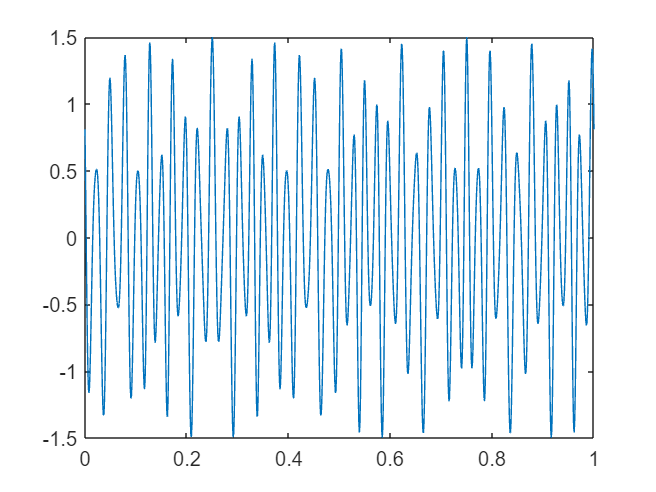

plot(t,signal);

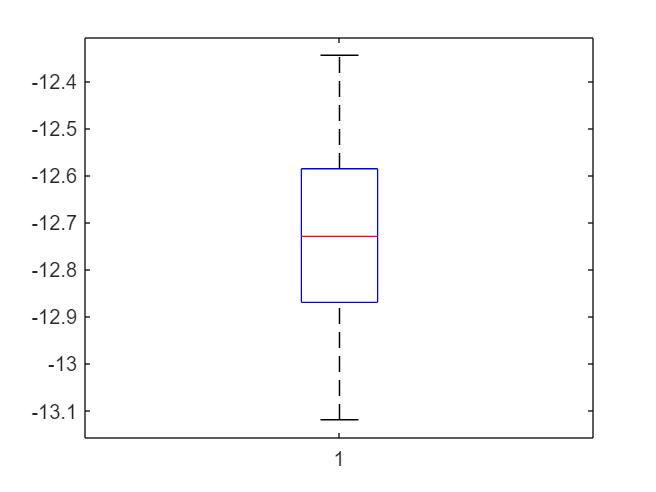

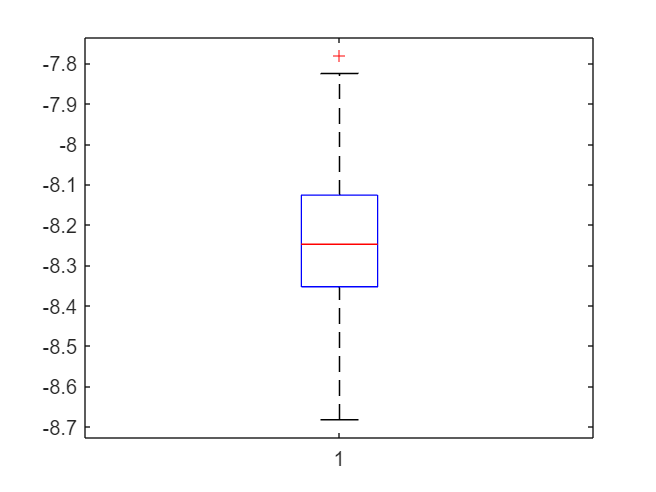

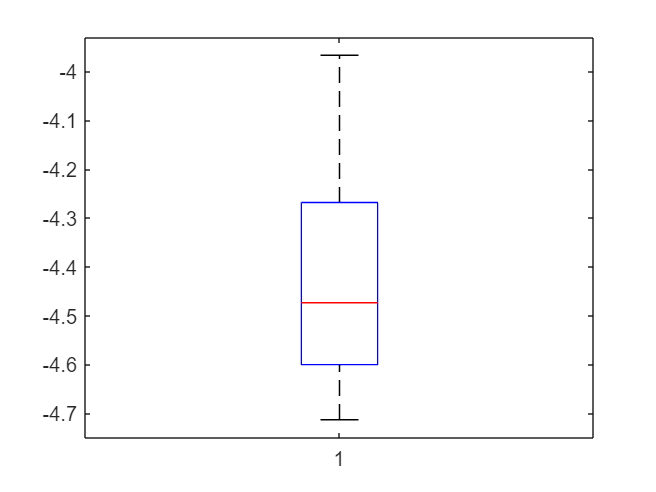

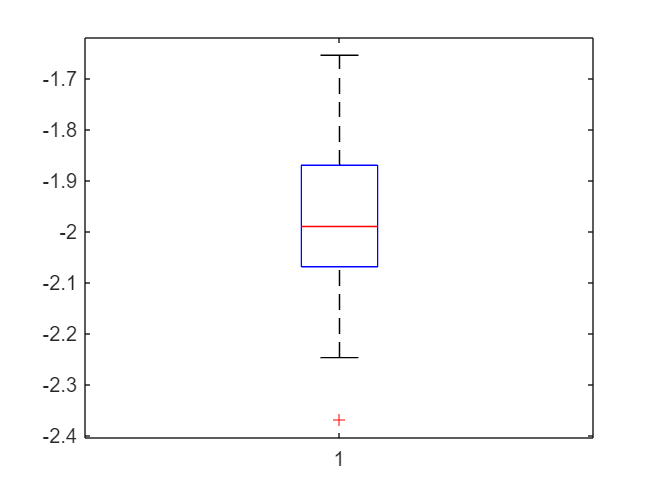

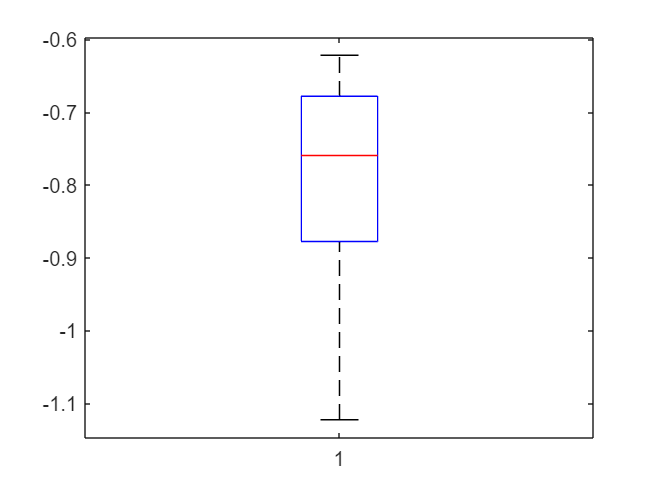

for nsr = -10:5:10
    Numtemp = 50;
    result = zeros(Numtemp,3);
    for atemp = 1:Numtemp
        raw = awgn(signal,nsr,0);
        filtered = emd_sc(raw)';
        [fsnr,fmse,fmae] = getEvaluation(filtered,signal)
        result(atemp,1) = fsnr;
        result(atemp,2) = fmse;
        result(atemp,3) = fmae;
    end
    figure('Name',"NSR="+nsr);
    boxplot(result(:,1));
end

function signal = generateSignal(t)
    signal = (1+0.5*cos(2*pi*24*t)).*cos(2*pi*40*t+cos(2*pi*5*t));
end

function filtered = emd_sc(signal)
    [imf,residual] = emd(signal);
    s = size(imf);
    K=s(2);
    for i=1:K
        cof = corrcoef(signal,imf(:,i));
        muy(i) = cof(1,2);
    end
    lamda = max(muy)/10;
    filtered = residual;
    for i=1:K
        if (muy(i)>=lamda)
            filtered = filtered+imf(:,i);
        end
    end
end

function filtered = emd_hd(signal)
    [imf,residual] = emd(signal);
    s = size(imf);
    K=s(2);
    for i=1:K
        cof = corrcoef(signal,imf(:,i));
        muy(i) = cof(1,2);
    end
    lamda = max(muy)/10;
    filtered = residual;
    for i=1:K
        if (muy(i)>=lamda)
            filtered = filtered+imf(:,i);
        end
    end
end
function [fsnr,fmse,fmae] = getEvaluation(filtered,signal)
    fmse = immse(filtered,signal);
    fmae = MAE(filtered,signal);
    fsnr = snr(signal,filtered);
end
% https://github.com/netskink/matlab/blob/master/MAE.m
function result = MAE(X,Y)
    result = sum( sum( abs(X-Y) ) ) / length( X(:) );
end